%Define network
net = network.IEEE9bus_;

%コントローラAGC
con_agc = controller.broadcast_PI_AGC(net,1:3,1:3,-100,-500);
net.add_controller_global(con_agc);

%コントローラレトロフィット
Q = [1, 1e8, 1,0];           
R  = 1e-5;
for i = 1:3
    con = controller.local_LQR_retrofit(net,i,diag(Q),diag(R));
    net.add_controller_local(con);
end

%初期値応答でテスト
%{
time = [0, 10];
option = struct();
option.x0_sys = net.x_equilibrium;
option.x0_sys(1) = option.x0_sys(1)+0.01;
out = net.simulate(time,option);
%}

%ロード変化でテスト
%{
u_idx = 5;
time   = [ 0, 1, 3,10];
u    = [ 0, 1, 0, 0 ;
         0, 0, 0, 0];
fault = {{[1,1.1],1}};
out = net.simulate(time,u_idx,u);
%}

%地絡応答でテスト
time = [0, 10];
fault = {{[1,1.1],1}};
out = net.simulate(time,'fault',fault);


 Simulation Start !!
 
0s                                                                                                10s
|        10%       20%       30%       40%       50%       60%       70%       80%       90%        |
|---------o---------o---------o---------o---------o---------o---------o---------o---------o---------|
|>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>|


%Define network without retrofit controllers
net = network.IEEE9bus_;

con_agc = controller.broadcast_PI_AGC(net,1:3,1:3,-100,-500);
net.add_controller_global(con_agc);

%地絡応答でテスト
time = [0, 10];
fault = {{[1,1.1],1}};
out2 = net.simulate(time,'fault',fault);


 Simulation Start !!
 
0s                                                                                                10s
|        10%       20%       30%       40%       50%       60%       70%       80%       90%        |
|---------o---------o---------o---------o---------o---------o---------o---------o---------o---------|
|>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>|


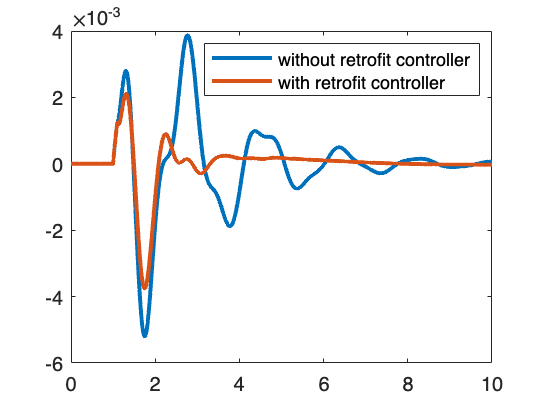

%Plot and compare
figure;
plot(out2.t, table2array(out2.X{1}(:,2)), 'LineWidth', 2)
hold on

plot(out.t, table2array(out.X{1}(:,2)), 'LineWidth', 2)

legend('without retrofit controller','with retrofit controller');